clear; clc; clear all

% AIRFOIL VARIABLES
gamma = 1.4

gamma = 1.4000

c = 1 %chord

c = 1


% Mach Numbers to be tested
%M1=[1.7,2] %test values for whcih I have hand calculated results
M1 = [1.3:0.1:3]

M1 =     1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


%M1 = [1.3,1.7,3]

% Deflections to be plotted
% theta1=[5,10] %test values for which I have hand calculated results
%t=0.01*[3,4,5,6,7,8,9,10]
%theta1 = atand(t./(c*0.5))

theta1 = [5:1:10] % associated colourmap

theta1 =      5     6     7     8     9    10


%t = 0.05
%theta1 = atand(2*t./c)
cmap = colormap(parula(length(theta1)+1));
t = (c*0.5)*tand(theta1) % associated thicknesses as a %

t =     0.0437    0.0526    0.0614    0.0703    0.0792    0.0882


% This relationship is basically linear for small angles

width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840];

%set(0,'defaulttextinterpreter','latex')

weak = 0 % This specifies we want the weak solution only - strong solutions are off condition

weak = 0


%Setting up the freestream inflow (this is trivial)
Pr1         = ones(length(theta1),length(M1));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Full Ideal Solver

%preallocation
x1          = zeros(length(theta1),length(M1));
x2          = zeros(length(theta1),length(M1));
H_exact     = zeros(length(theta1),length(M1));
h_star_exact= zeros(length(theta1),length(M1));
A_ratio     = zeros(length(theta1),length(M1));
M2          = zeros(length(theta1),length(M1));
M3          = zeros(length(theta1),length(M1));
theta2      = zeros(length(theta1),length(M1));
phi1        = zeros(length(theta1),length(M1));
phi2        = zeros(length(theta1),length(M1));
Pr2         = zeros(length(theta1),length(M1));
Pr3         = zeros(length(theta1),length(M1));
beta1       = zeros(length(theta1),length(M1));
beta2       = zeros(length(theta1),length(M1));

for j = 1:length(theta1)
    theta = theta1(j);
    for i=1:length(M1)
        machno = M1(i);
[x1(j,i),x2(j,i),H_exact(j,i),h_star_exact(j,i),A_ratio(j,i),beta1(j,i),beta2(j,i),M2(j,i),M3(j,i),theta2(j,i),phi1(j,i),phi2(j,i),Pr2(j,i),Pr3(j,i)] = IdealSpacing(machno,theta,c,gamma);
    end
end

No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No Solution - consider higher Mach Number
No Solution - consider higher Mach Number
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle
No weak solution - consider a higher Mach or Lower Deflection Angle



H_exact

H_exact =        NaN       NaN    0.6410    0.5446    0.4834    0.4390    0.4048    0.3772    0.3543    0.3350    0.3183    0.3038    0.2910    0.2795    0.2693    0.2601    0.2517    0.2441
       NaN       NaN    0.7326    0.5881    0.5150    0.4651    0.4276    0.3979    0.3736    0.3532    0.3357    0.3206    0.3073    0.2955    0.2850    0.2755    0.2669    0.2591
       NaN       NaN       NaN    0.6472    0.5519    0.4940    0.4523    0.4200    0.3939    0.3723    0.3540    0.3381    0.3243    0.3121    0.3013    0.2915    0.2827    0.2747
       NaN       NaN       NaN       NaN    0.5981    0.5268    0.4793    0.4437    0.4155    0.3925    0.3731    0.3565    0.3421    0.3294    0.3182    0.3081    0.2991    0.2909
       NaN       NaN       NaN       NaN    0.6830    0.5661    0.5095    0.4695    0.4387    0.4138    0.3932    0.3757    0.3606    0.3474    0.3358    0.3254    0.3161    0.3077
       NaN       NaN       NaN       NaN       NaN    0.6208    0.5447    0.4980    0


% Net Pressure Rise
TotalPr = Pr3.*Pr2.*Pr1;

## Plotting Spacings

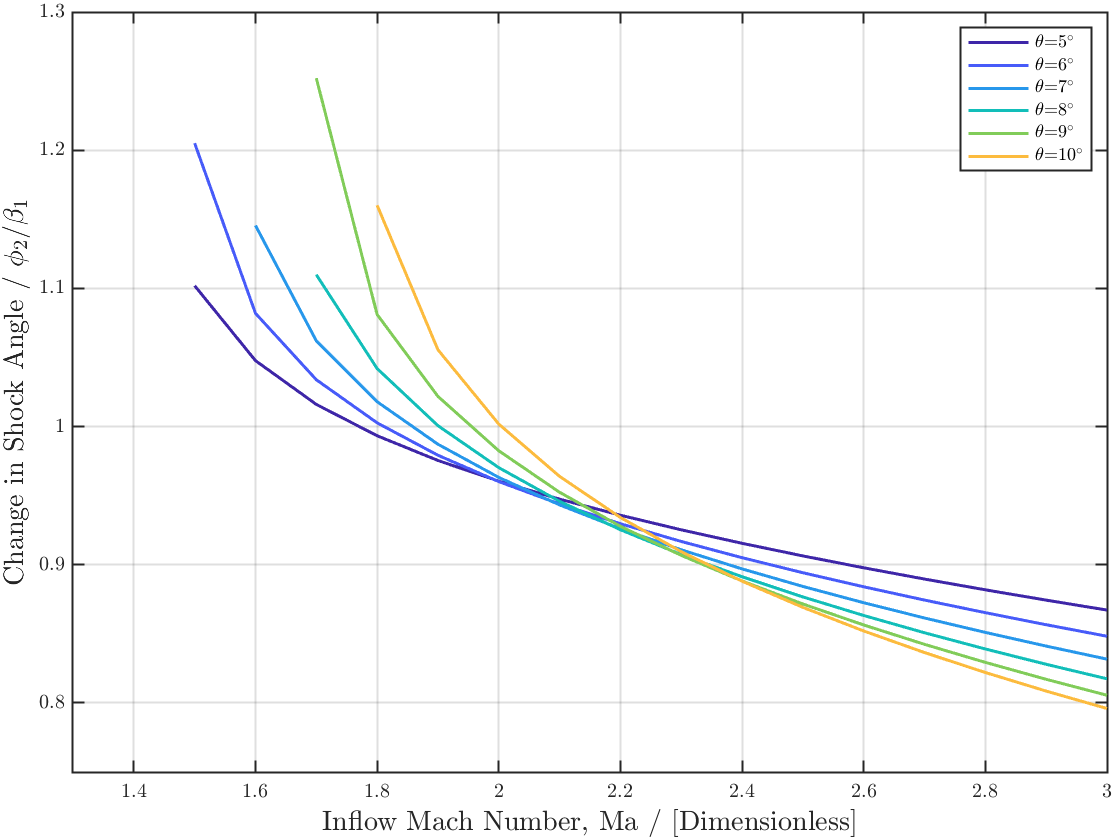

anglechange=phi2./beta1;

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

figure
for line = 1:length(theta1)
plot(M1,anglechange(line,:),'-','Color',cmap(line,:),"LineWidth",width)
hold on
end
xlabel("Inflow Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Change in Shock Angle / $\phi_{2}/\beta_{1}$",'FontSize',lsize)
%title("\textbf{Change in Shock Angle}",'FontSize',tsize)
legend(legendCelltheta,'FontSize',legsize)
grid on
box on
xlim([min(M1),max(M1)])
ylim([0.75,1.3])
hold off
InSet = get(gca, 'TightInset');
grid on; hold off; box on
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Kusunose et al. (2011)
Jpn_Mach = 1.7; Jpn_t = 0.05; Jpn_H = 0.505

Jpn_H = 0.5050

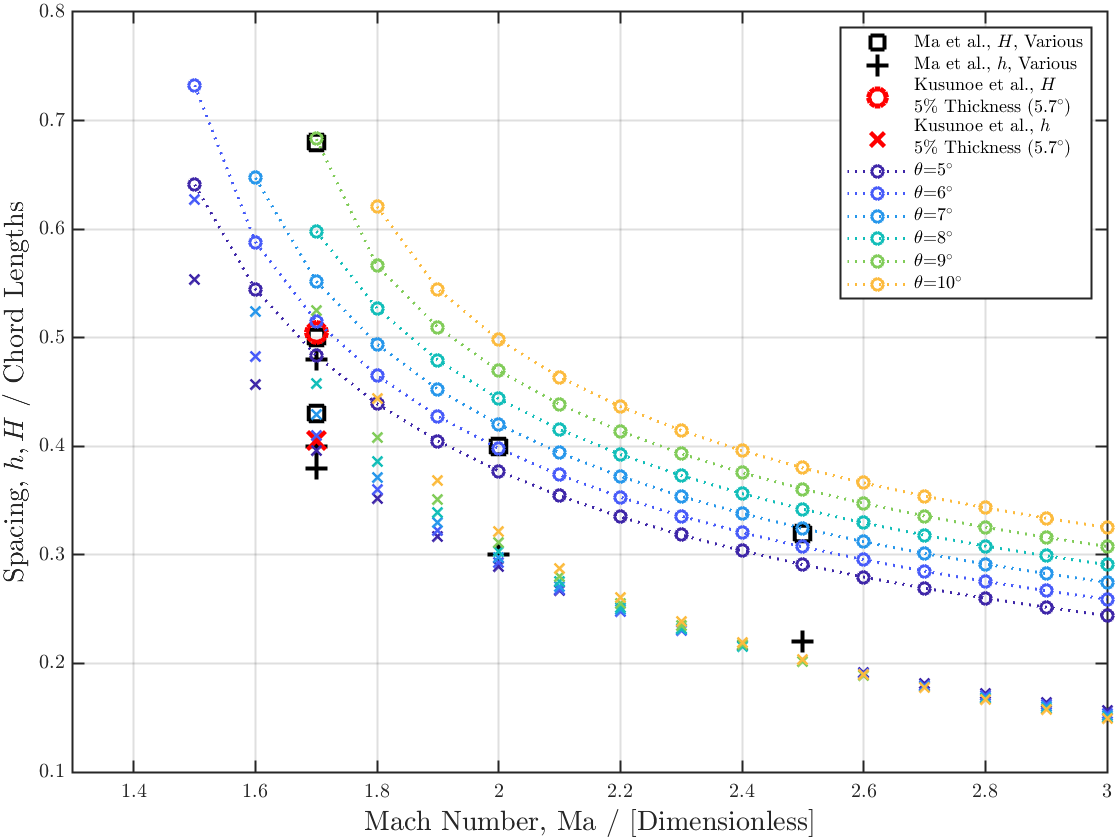

H_exact;
Jpn_h = Jpn_H-(2*Jpn_t); Jpn_Ar = Jpn_h/Jpn_H;

%Ma et al
Mappr_Mach = [1.7,1.7,1.7,2,2.5];
Mappr_t = [0.025,0.05,0.1,0.05,0.05];
Mappr_H = [0.43,0.50,0.68,0.40,0.32];
Mappr_h = Mappr_H-(2.*Mappr_t); Mappr_Ar = Mappr_h./Mappr_H;

figure
%subplot(2,2,1)
plot(Mappr_Mach, Mappr_H,'sk',"LineWidth",2,"MarkerSize",msize+2)
hold on
plot(Mappr_Mach, Mappr_h,'+k',"LineWidth",2,"MarkerSize",msize+2)
plot(Jpn_Mach, Jpn_H,'or',"LineWidth",2.5,"MarkerSize",msize+2)
hold on
plot(Jpn_Mach, Jpn_h,'xr',"LineWidth",2.5,"MarkerSize",msize+2)

for line = 1:length(theta1)
plot(M1,H_exact(line,:),'o:','Color',cmap(line,:),"LineWidth",width,"MarkerSize",msize)
hold on
end
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize,"MarkerSize",msize)
ylabel("Spacing, $h,H$ / Chord Lengths",'FontSize',lsize)
for line = 1:length(theta1)
plot(M1,h_star_exact(line,:),'x','Color',cmap(line,:),"LineWidth",width,"MarkerSize",msize)
hold on
end
%title("\textbf{Exact Spacing}",'FontSize',tsize)
legend([{['Ma et al., $H$, Various']},{['Ma et al., $h$, Various']},{['Kusunoe et al., $H$' newline '5\% Thickness (5.7$^{\circ}$)']},{['Kusunoe et al., $h$' newline '5\% Thickness (5.7$^{\circ}$)']},legendCelltheta],'location','northeast','FontSize',legsize)
grid on
box on
xlim([min(M1),max(M1)])
ylim([0.0,1.2])
ylim([0.1,0.8])
InSet = get(gca, 'TightInset');
grid on; hold off; box on
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Choking and Area Ratio

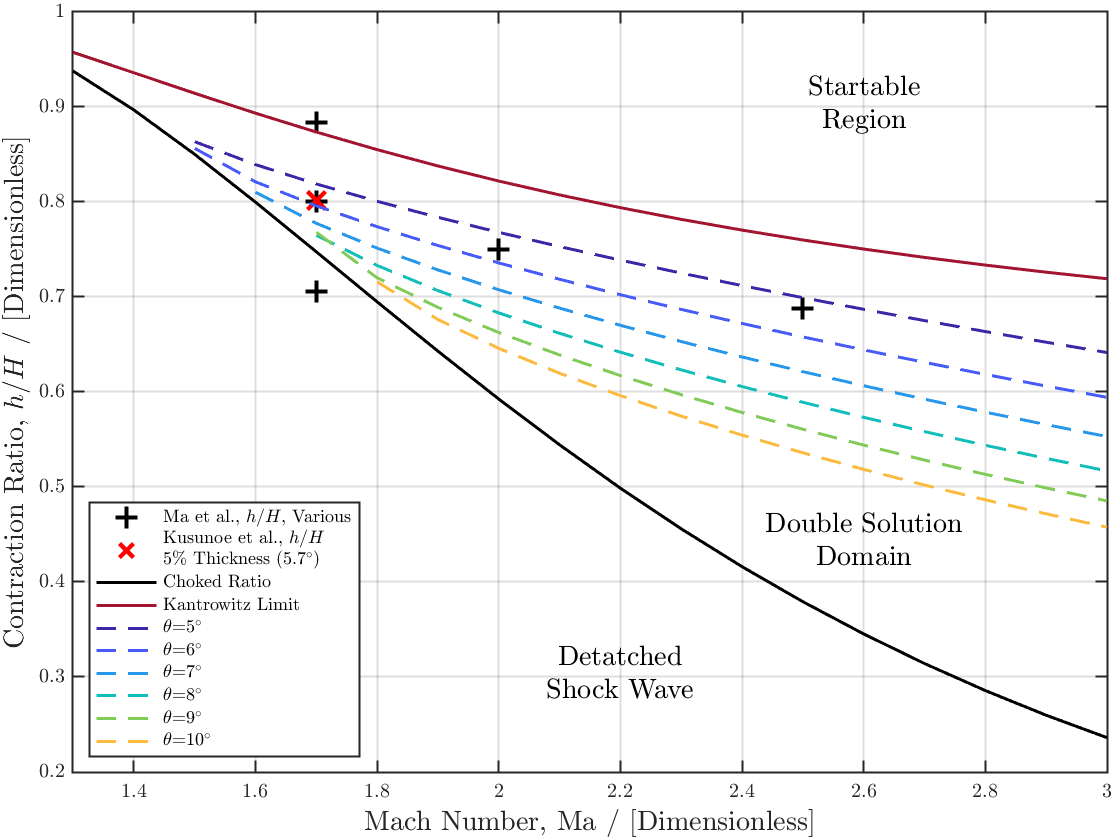

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Chocked_Area=zeros(1,length(M1));
for n=1:length(M1)
    Chocked_Area(n) = 1./Area_Ratio(M1(n),gamma);
end

Kantrowitz_Limit=zeros(1,length(M1));
for n=1:length(M1)
    Kantrowitz_Limit(n) = Kantrowitz(M1(n),gamma);
end
figure
%subplot(2,2,1)
plot(Mappr_Mach, Mappr_Ar,'+k',"LineWidth",2,"MarkerSize",msize+2)
hold on
plot(Jpn_Mach, Jpn_Ar,'xr',"LineWidth",2.5,"MarkerSize",msize+2)
hold on
plot(M1,Chocked_Area,'k-',"LineWidth",width)
plot(M1,Kantrowitz_Limit,'-',"LineWidth",width,"Color",red)
hold on
for line = 1:length(theta1)
    plot(M1,A_ratio(line,:),'--','Color',cmap(line,:),"LineWidth",width)
    hold on
end
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Contraction Ratio, $h/H$ / [Dimensionless]",'FontSize',lsize)
%title("\textbf{Exact Contraction Ratio}",'FontSize',tsize)
legend([{['Ma et al., $h/H$, Various']},{['Kusunoe et al., $h/H$' newline '5\% Thickness (5.7$^{\circ}$)']},"Choked Ratio","Kantrowitz Limit",legendCelltheta],'Location','southwest','FontSize',legsize)
grid on
text1={'Detatched','Shock Wave'};   textx1=2.2;  height1=0.3;
text2={'Double Solution','Domain'}; textx2=2.6; height2=0.44;
text3={'Startable','Region'};       textx3=2.6;  height3=0.9;
t1 = text(textx1,height1,text1); t1.FontSize = tsize; t1.HorizontalAlignment = 'center';
t2 = text(textx2,height2,text2); t2.FontSize = tsize; t2.HorizontalAlignment = 'center';
t3 = text(textx3,height3,text3); t3.FontSize = tsize; t3.HorizontalAlignment = 'center';
box on
xlim([min(M1),max(M1)])
ylim([0.2,1.0])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## Initial Expansion

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Flow field at the central point: M3
% Relative direction = 0deg, turn = theta1

M3(M3 < 1) = NaN; %Gets rid of the subsonic central regioned pts

mu1 = asind(1./M3);
phi_startExp = mu1;

v_M4 = transpose(theta1)+PrandtlMeyer(M3,gamma);
M4 = InvPrandtlMeyer(v_M4);

mu2 = asind(1./M4);
phi_endExp = mu2-transpose(theta1);

## Fast Method of Expansions

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This essentially breaks the expansions down into three length
% x3 = distance covered to meet at the centerline 
% F1, distance travelled for expansion head wave to hit other side
% F2, distnace travelled for rtail wave to hit other side
% if all works out then this distance (F2) shoucl be
% half a chord length.

% THIS FAST METHOD DOES NOT ACCOUNT FOR EXPANSION-EXPANSION INTERACTION

% x3
x_3 = (h_star_exact/2)./tand(phi_startExp);

% F2
F2 = (H_exact-transpose(t)).*tand(90-phi_endExp);
Overexpansion_length = F2-0.5;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% F1
F1 = (h_star_exact.*tand(90-phi_startExp)) ./ (1-(2.*transpose(t)).*tand(90-phi_startExp));

## AREA RATIO METHOD

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% So here we have an expansion from A1 to A2 i.e. h to H
% This equates to a mach increase (or should) from M3 to M5
% We use a supersonic (chocked) reference condion: (A2/A*) = (A2/A1)(A1/A*)

%(A2/A1)
Overall_Exp_Ratio = H_exact./h_star_exact;

%(A1/A*)
Start_Mach_ARatio = Area_Ratio(M3,gamma);

% The calculation
Final_Mach_ARatio = Overall_Exp_Ratio.*Start_Mach_ARatio;

M5_AR = zeros(size(M3));

for i = 1:length(theta1)
    for j = 1:length(M1)
M5_AR(i,j) = Inv_Area_Ratio(Final_Mach_ARatio(i,j),gamma);
    end 
end

Recovery_MachRatio_AR = 100*(M5_AR./M1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Inital Drag Calculations

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Renaming due to earlier flaws
P1 = Pr1;
P2 = Pr2;
P3 = TotalPr;

% We can obtain the pressures of the expansions as such
P4 = isentropicPr(M3,M4,P3,gamma);
P5 = isentropicPr(M4,M5_AR,P4,gamma); %(Assumed we can scale with the Mach number of outflow) 
Pv = 0.5*(P4+P5);

% Dynamic Head in terms of 1/P_inf
q_inf = 0.5*gamma*P1.*M1.^2;

% Associated Pressure coefficients
Cp1 = P1.*(P1-1)./q_inf;
Cp2 = P1.*(P2-1)./q_inf;
Cp3 = P1.*(P3-1)./q_inf;
Cp4 = P1.*(P4-1)./q_inf;
Cpv = P1.*(Pv-1)./q_inf;
Cp5 = P1.*(P5-1)./q_inf;

% Associated Lengths for Drag
l2 = sqrt(t.^2+(c/2).^2);
l4 = F1./transpose(cosd(theta1));
lv = transpose(l2)-(l4);
%lv = F2./transpose(cosd(theta1));

% Area
% Unsure if to use projected, planform or a thickness based assumption
% Area = 2*t
Area = 1; %Unit area - PLANFORM i.e. one surface only

% Total Drag
Drag = 2*P1.*transpose(sind(theta1)).*((transpose(l2).*P2)-(l4.*P4)-(lv.*Pv));

% Total Cd
Cd = Drag./(q_inf.*transpose(Area))

Cd =        NaN       NaN    0.0031    0.0018    0.0013    0.0010    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003
       NaN       NaN       NaN    0.0038    0.0025    0.0019    0.0015    0.0013    0.0011    0.0010    0.0009    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005
       NaN       NaN       NaN    0.0084    0.0046    0.0033    0.0026    0.0021    0.0018    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0009    0.0008
       NaN       NaN       NaN       NaN    0.0088    0.0057    0.0043    0.0035    0.0029    0.0025    0.0022    0.0020    0.0018    0.0017    0.0015    0.0014    0.0013    0.0013
       NaN       NaN       NaN       NaN       NaN    0.0097    0.0069    0.0054    0.0045    0.0038    0.0034    0.0030    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018
       NaN       NaN       NaN       NaN       NaN    0.0194    0.0110    0.0082    0.0067


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## HU ET AL. 2011/2012

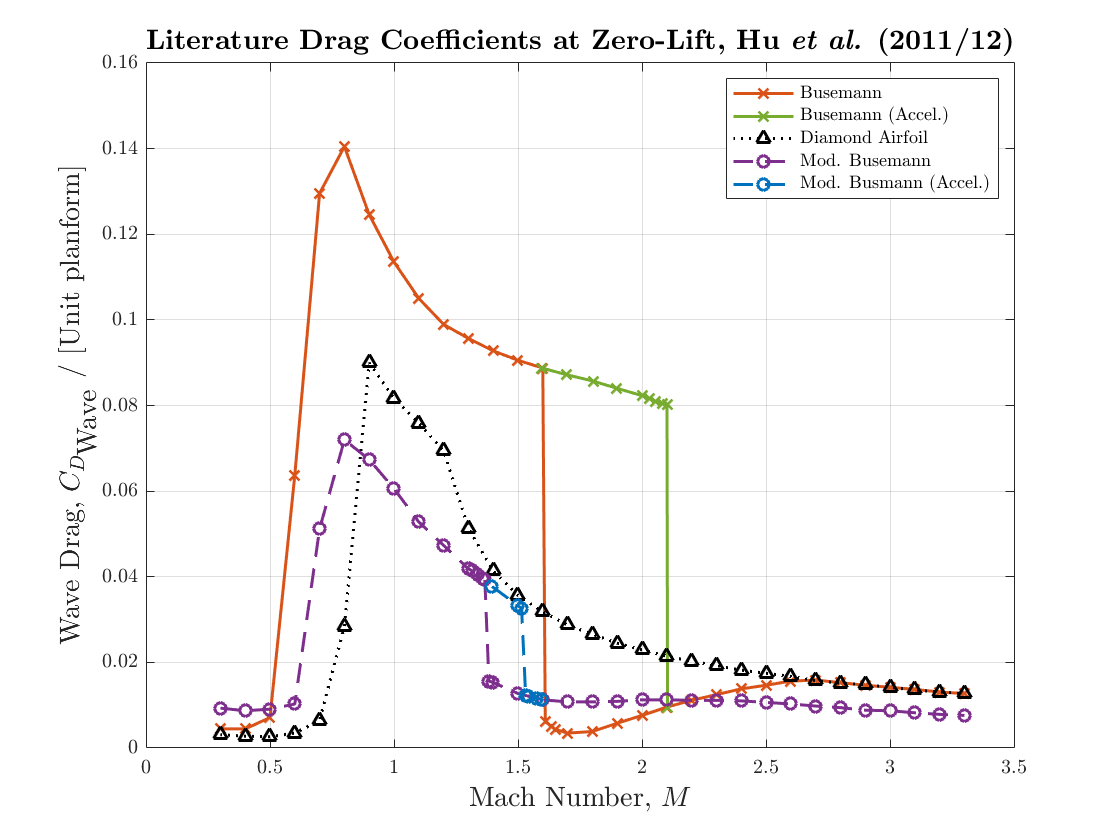


%FIG 16 - DRAG PLOT  - zero lift, Machs and Wave drags
%busemann
Hu_et_al_fig16_buseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.61,1.633744856,1.652263374,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_buseman_cd=[0.004453441,0.004453441,0.007125506,0.063724696,0.129554656,0.14048583,0.124574899,0.113522267,0.105020243,0.098947368,0.095668016,0.092753036,0.090566802,0.088744939,0.006153846,0.005060729,0.004331984,0.003481781,0.003846154,0.005789474,0.007611336,0.009554656,0.011133603,0.012469636,0.013805668,0.01465587,0.01562753,0.015870445,0.015263158,0.01465587,0.01417004,0.013684211,0.013076923,0.012712551];
%busemann accel
Hu_et_al_fig16_buseman_accel_machs=[1.596707819,1.697530864,1.802469136,1.899176955,2,2.030864198,2.053497942,2.082304527,2.100823045,2.102880658];
Hu_et_al_fig16_buseman_accel_cd=[0.088744939,0.087165992,0.085708502,0.084008097,0.082307692,0.081578947,0.08097166,0.08048583,0.080121457,0.009554656];
%diamond
Hu_et_al_fig16_diamond_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_diamond_cd=[0.003117409,0.002753036,0.002631579,0.003481781,0.006396761,0.028380567,0.089959514,0.081700405,0.075870445,0.069433198,0.051336032,0.041376518,0.035668016,0.031781377,0.028744939,0.026558704,0.024493927,0.02291498,0.02145749,0.020242915,0.019271255,0.018178138,0.017449393,0.016720648,0.015748988,0.0151417,0.014777328,0.01417004,0.013562753,0.013076923,0.012712551];
%modified accel
Hu_et_al_fig16_modifiedbuseman_accel_machs=[1.395061728,1.5,1.514403292,1.530864198,1.541152263,1.574074074,1.596707819];
Hu_et_al_fig16_modifiedbuseman_accel_cd=[0.037732794,0.033238866,0.032631579,0.012226721,0.011983806,0.011619433,0.011376518];
%modified
Hu_et_al_fig16_modifiedbuseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.314814815,1.335390947,1.355967078,1.366255144,1.382716049,1.397119342,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_modifiedbuseman_cd=[0.009311741,0.008704453,0.009068826,0.010283401,0.051214575,0.071983806,0.067368421,0.060566802,0.052793522,0.047327935,0.041862348,0.041376518,0.040526316,0.039676113,0.039311741,0.01562753,0.015384615,0.012712551,0.011255061,0.010769231,0.010769231,0.010890688,0.011255061,0.011255061,0.011133603,0.011133603,0.011012146,0.010647773,0.010283401,0.009797571,0.009433198,0.008825911,0.008704453,0.008218623,0.007854251,0.007611336];

figure
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'x-',"LineWidth",width,'color',[0.8500 0.3250 0.0980])
hold on
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'x-',"LineWidth",width,'color',[0.4660 0.6740 0.1880])
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'^:',"LineWidth",width,'color',[0 0 0])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o--',"LineWidth",width,'color',[0.4940 0.1840 0.5560])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o--',"LineWidth",width,'color',[0 0.4470 0.7410])
xlabel("Mach Number, $M$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients at Zero-Lift, Hu \textit{et al.} (2011/12)}",'FontSize',tsize)
legend("Busemann","Busemann (Accel.)","Diamond Airfoil","Mod. Busemann","Mod. Busmann (Accel.)", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
box on
grid on
hold off

## Kusunose et al (2011)

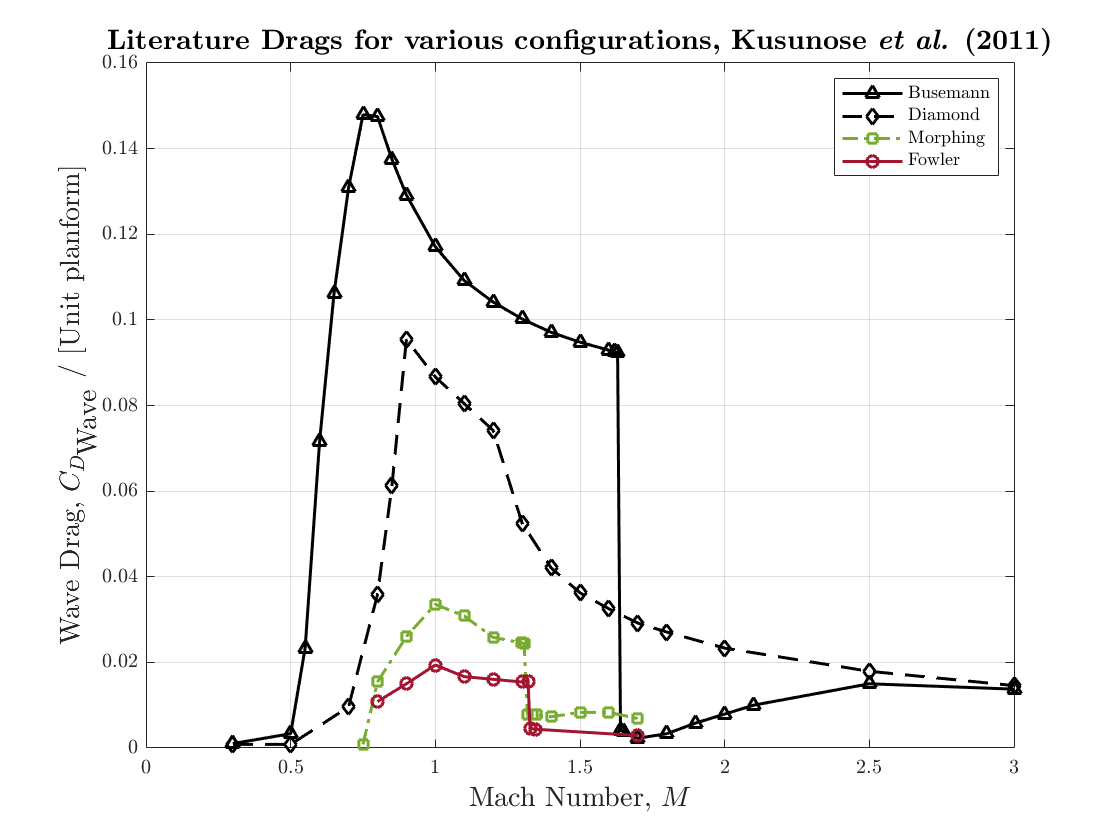

% KUSUNOSE  - Supersonic biplane—A review

%FIG 18 - cdwave across machs for 4 different airfoils
%busemann		diamond airfoil		morphing		fowler
Kusunose_review_fig18_buseman_machs=[0.3,0.5,0.55,0.6,0.65,0.7,0.75,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.62,1.63,1.64,1.65,1.7,1.8,1.9,2,2.1,2.5,3];
Kusunose_review_fig18_buseman_cd=[0.001041667,0.003333333,0.023333333,0.071666667,0.10625,0.130833333,0.147916667,0.1475,0.1375,0.129166667,0.117083333,0.109166667,0.104166667,0.100208333,0.097083333,0.094791667,0.092916667,0.0925,0.092291667,0.004166667,0.00375,0.002291667,0.003333333,0.005833333,0.007916667,0.01,0.015,0.01375];

Kusunose_review_fig18_diamond_machs=[0.3,0.5,0.7,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.7,1.8,2,2.5,3];
Kusunose_review_fig18_diamond_cd=[0.000833333,0.000833333,0.009583333,0.035833333,0.06125,0.095416667,0.086666667,0.080416667,0.074166667,0.0525,0.042083333,0.03625,0.0325,0.029166667,0.027083333,0.023333333,0.017916667,0.014583333];

Kusunose_review_fig18_morphing_machs=[0.75,0.8,0.9,1,1.1,1.2,1.297727273,1.306818182,1.318181818,1.336363636,1.35,1.4,1.5,1.6,1.7];
Kusunose_review_fig18_morphing_cd=[0.000833333,0.015416667,0.026041667,0.033541667,0.030833333,0.025833333,0.024583333,0.024375,0.007916667,0.007916667,0.007708333,0.007291667,0.008333333,0.008333333,0.006875];

Kusunose_review_fig18_fowler_machs=[0.8,0.9,1,1.1,1.2,1.3,1.3,1.320454545,1.327272727,1.347727273,1.7];
Kusunose_review_fig18_fowler_cd=[0.010833333,0.015,0.019375,0.016666667,0.016041667,0.015416667,0.015625,0.015625,0.004583333,0.004375,0.002916667];

figure
plot(Kusunose_review_fig18_buseman_machs,Kusunose_review_fig18_buseman_cd,'k^-',"LineWidth",width)
hold on
plot(Kusunose_review_fig18_diamond_machs,Kusunose_review_fig18_diamond_cd,'kd--',"LineWidth",width)
hold on
plot(Kusunose_review_fig18_morphing_machs,Kusunose_review_fig18_morphing_cd,'s-.',"LineWidth",width,'color',[0.4660 0.6740 0.1880])
hold on
plot(Kusunose_review_fig18_fowler_machs,Kusunose_review_fig18_fowler_cd,'o-',"LineWidth",width,'color',[0.6350 0.0780 0.1840])
xlabel("Mach Number, $M$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drags for various configurations, Kusunose \textit{et al.} (2011)}",'FontSize',tsize)
legend("Busemann","Diamond","Morphing","Fowler", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.16]);
box on
grid on
hold off

## Drag Comparison

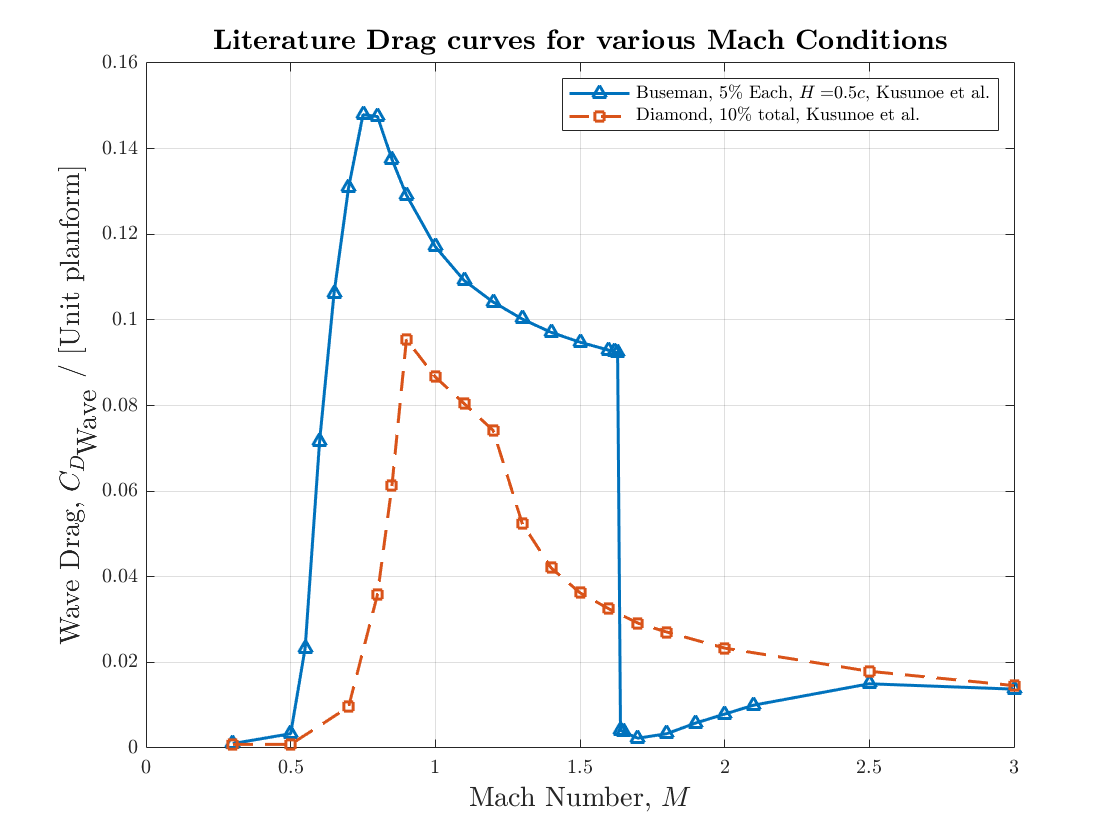

% Comparison to previuous data

% Kusunose et al. (2011)
MachRuns_buse = Kusunose_review_fig18_buseman_machs;
MachRuns_dia = Kusunose_review_fig18_diamond_machs;
Jpn_Busemann = Kusunose_review_fig18_buseman_cd;
Jpn_Diamond = Kusunose_review_fig18_diamond_cd;

%Jpn_alphas = [0:0.5:3.5];
%Jpn_dia_cl_euler =[0,0.0257,0.0515,0.0773,0.1031,0.1290,0.1550,0.1810];
%Jpn_dia_cdw_euler =[0.02891, 0.02914, 0.02983, 0.0316, 0.03264, 0.03475, 0.03734, 0.04041];
%Jpn_dia_LoverD_euler =Jpn_dia_cl_euler./Jpn_dia_cdw_euler;

figure
plot(MachRuns_buse,Jpn_Busemann,'^-',"LineWidth",width)
hold on
plot(MachRuns_dia,Jpn_Diamond,'s--',"LineWidth",width)
xlabel("Mach Number, $M$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag curves for various Mach Conditions}",'FontSize',tsize)
legend("Buseman, 5\% Each, $H=$0.5$c$, Kusunoe et al.","Diamond, 10\% total, Kusunoe et al.", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.16]);
box on
grid on
hold off

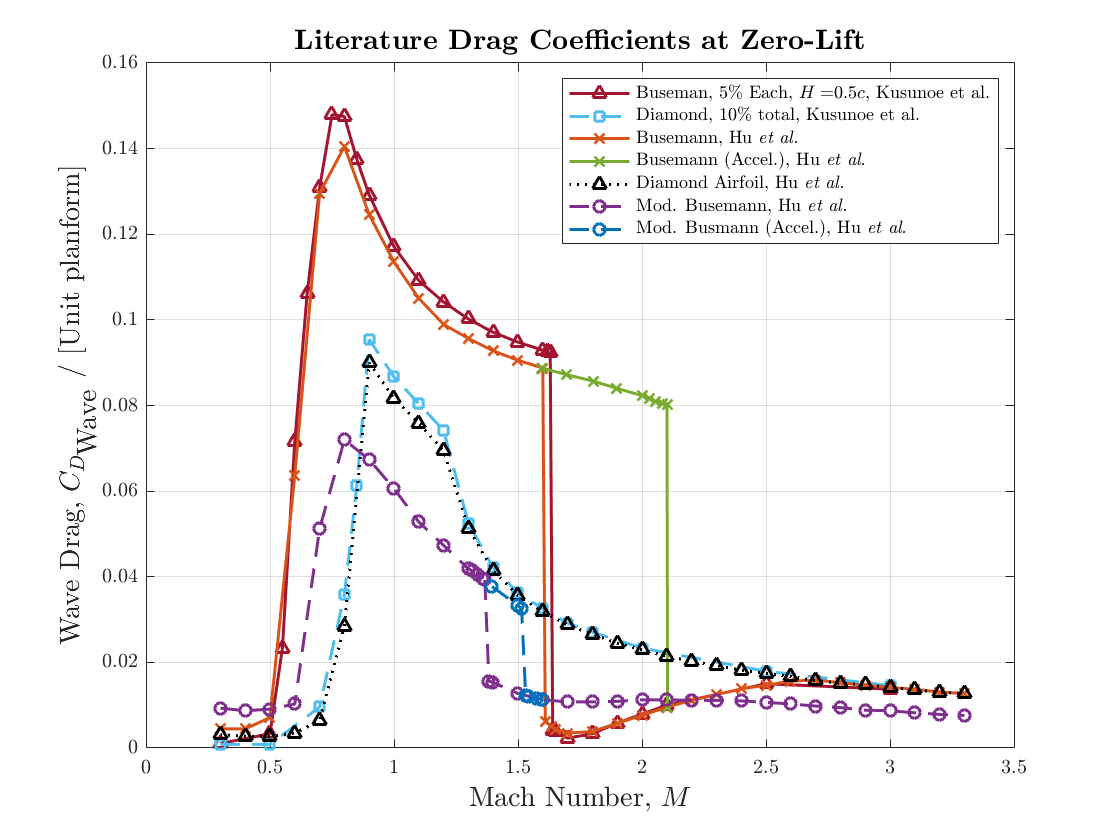


figure
plot(MachRuns_buse,Jpn_Busemann,'^-',"LineWidth",width,'color',[0.6350 0.0780 0.1840])
hold on
plot(MachRuns_dia,Jpn_Diamond,'s--',"LineWidth",width,'color',[0.3010 0.7450 0.9330])
hold on
plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'x-',"LineWidth",width,'color',[0.8500 0.3250 0.0980])
hold on
plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'x-',"LineWidth",width,'color',[0.4660 0.6740 0.1880])
hold on
plot(Hu_et_al_fig16_diamond_machs,Hu_et_al_fig16_diamond_cd,'^:',"LineWidth",width,'color',[0 0 0])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_machs,Hu_et_al_fig16_modifiedbuseman_cd,'o--',"LineWidth",width,'color',[0.4940 0.1840 0.5560])
hold on
plot(Hu_et_al_fig16_modifiedbuseman_accel_machs,Hu_et_al_fig16_modifiedbuseman_accel_cd,'o--',"LineWidth",width,'color',[0 0.4470 0.7410])
xlabel("Mach Number, $M$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Literature Drag Coefficients at Zero-Lift}",'FontSize',tsize)
legend("Buseman, 5\% Each, $H=$0.5$c$, Kusunoe et al.","Diamond, 10\% total, Kusunoe et al.","Busemann, Hu \textit{et al.}","Busemann (Accel.), Hu \textit{et al.}","Diamond Airfoil, Hu \textit{et al.}","Mod. Busemann, Hu \textit{et al.}","Mod. Busmann (Accel.), Hu \textit{et al.}", "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0 0.16])
box on
grid on
hold off

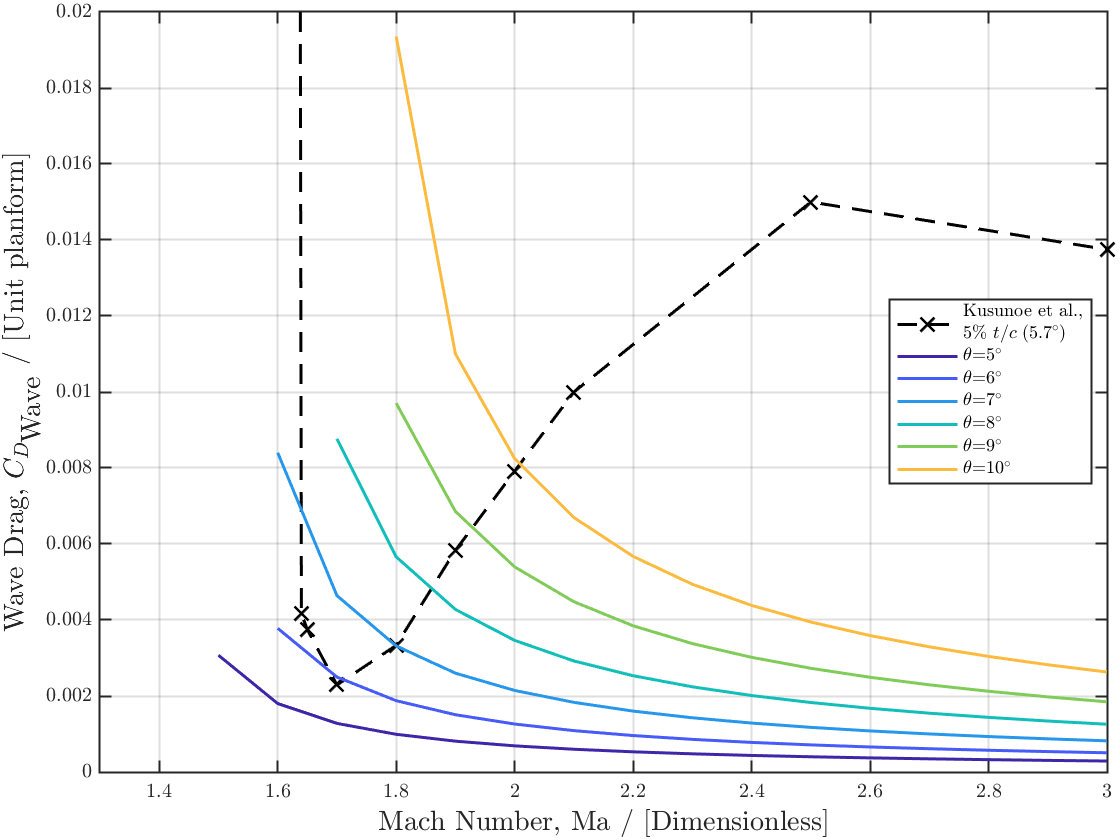


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Japanese point performance Drag Results: 
% Optimal Point
Jpn_Mach = 1.7;
Jpn_CDWave = Jpn_Busemann(22);

figure
plot(MachRuns_buse,Jpn_Busemann,'x--k',"LineWidth",width,"MarkerSize",8)
%plot(Jpn_Mach,Jpn_CDWave,'xk',"LineWidth",1.5)
hold on
for line = 1:length(theta1)
plot(M1,Cd(line,:),'Color',cmap(line,:),"LineWidth",width)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend([{['Kusunoe et al.,' newline '5\% $t/c$ (5.7$^{\circ}$)']},legendCelltheta],'location','east','FontSize',legsize)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
%title("\textbf{Minima loci for optimally spaced biplanes at increasing mach numbers}",'FontSize',tsize)
grid on
ylim([0,0.02])
xlim([min(M1),max(M1)])
box on
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


DiamondDragAtMach = Jpn_Diamond(14)

DiamondDragAtMach = 0.0292

Mimimium_Kusunose = Jpn_Busemann(22)

Mimimium_Kusunose = 0.0023

Theorietical_Optimal = Cd

Theorietical_Optimal =        NaN       NaN    0.0031    0.0018    0.0013    0.0010    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003
       NaN       NaN       NaN    0.0038    0.0025    0.0019    0.0015    0.0013    0.0011    0.0010    0.0009    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005
       NaN       NaN       NaN    0.0084    0.0046    0.0033    0.0026    0.0021    0.0018    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0009    0.0008
       NaN       NaN       NaN       NaN    0.0088    0.0057    0.0043    0.0035    0.0029    0.0025    0.0022    0.0020    0.0018    0.0017    0.0015    0.0014    0.0013    0.0013
       NaN       NaN       NaN       NaN       NaN    0.0097    0.0069    0.0054    0.0045    0.0038    0.0034    0.0030    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018
       NaN       NaN       NaN       NaN       NaN    0.0194    0.0110  


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Japanese Mach Range

function Area = Area_Ratio(M,gamma)
% This function returns the Area (expansion) Ratio required to expand a flow
% from the sonic line for a given Mach number (M) ratio of specific heats
% (gamma). This finds it uses in rocket nozzles hence we invert it
% elsewhere in the code.

a=0.5*(gamma+1);
b=(gamma+1)/(2*(gamma-1));
c=1+((0.5*(gamma-1))*M.^2);

Area = (a^-b).*((c.^b)./M);
end

function Area_rat = Kantrowitz(M,gamma)
% This function returns the Katrowitz limit for a given Mach number
% That is the region above which the bow shock will be swallowed and there
% will be a single solution - started

a= (((gamma-1)*M.^2)+2)/((gamma+1)*M.^2) ;
b= ((2*gamma*M.^2)-(gamma-1)) /((gamma+1)*M.^2);

Area_rat = sqrt(a)*(b^(1/(gamma-1)));
end

function Mach = Inv_Area_Ratio(AreaRatio,gamma)
if isnan(AreaRatio) == true
    Mach = NaN;
else
% Based on Root Finding Methods by: JoshTheEngineer
% (www.joshtheengineer.com)
%  - Solve the Area-Mach Number equation for Mach number
g   = gamma;
gm1 = g-1;
gp1 = g+1;

% Define anonymous function with two inputs (M and ARatio)
% - Pass M and ARatio as arguments to AM_EQN to get function value
% -     funVal = AM_EQN(M,ARatio)
%AM_EQN = @(M,ARatio) sqrt((1/M^2)*(((2+gm1*M^2)/gp1)^(gp1/gm1)))-ARatio;

% Solve for Msub and Msup using this area ratio (A/A*)
ARatio = AreaRatio;

% Error tolerance
%errTol = 1e-4;

%% MATLAB SOLVER

% Set up the solver
problem.objective = @(M) (1/M^2)*(((2+gm1*M^2)/gp1)^(gp1/gm1))-ARatio^2;    % Objective function
problem.solver    = 'fzero';              % Find the zero
problem.options   = optimset(@fzero);     % Default options

% Solve subsonic root
problem.x0 = [1e-6 1];              % Subsonic solver bounds
Msub       = fzero(problem);        % Solve for subsonic M
problem.x0 = [1+1e-6 50];           % Supersonic solver bounds
Msup       = fzero(problem);        % Solve for supersonic M

% Print solutions to command window
% fprintf('==== MATLAB SOLVER ====\n');
% fprintf('Msub: %3.4f\n',Msub);
% fprintf('Msup: %3.4f\n',Msup);
% fprintf('=======================\n\n');
Mach = Msup;
end
end

function [x1,x2,H_exact,h_star_exact,A_ratio,beta1,beta2,M2,M3,theta2,phi1,phi2,Pr2,Pr3]=IdealSpacing(M1,theta1,chord,gamma)

% STEP 1
t = (chord*0.5)*tand(theta1);

% STEP 2
[beta1,M2,Pr2] = ObliqueShock(M1,theta1,gamma);
%[beta1,M2,Pr2,P0r2,rhor2,tr2,M1n,M2n] = ObliqueShock(M1,theta1,gamma);
phi1 = beta1-theta1;

% STEP 3
theta2=theta1;
[beta2,M3,Pr3] = ObliqueShock(M2,theta2,gamma);
%[beta2,M3,Pr3,P0r3,rhor3,Tr3,M2n,M3n] = ObliqueShock(M2,theta2,gamma);
phi2 = beta2-theta2;

% STEP 4
alpha = 180-beta2-phi1;

% STEP 5
L = sqrt( ((0.5*chord)^2) + (t^2) );
r = (L/sind(alpha)) * sind(beta2); %sine rule

% STEP 6
x1 = r*cosd(beta1);
x2 = (0.5*chord)-x1;
dy = r*sind(beta1);

% STEP 7
H_exact = 2*dy;
h_star_exact = H_exact-(2*t);
A_ratio = h_star_exact/H_exact;
end

function [beta,M2,Pr2,P0r2,rhor2,Tr2,M1n,M2n] = ObliqueShock(M1,theta,gamma)

% GIVEN upstream Mach M1, deflection angle theta and spec. heat ratio gamma
% Returns the down stream Mach number, M2 and it's Normal Component M2N
% and the vatious ratios of quantities based on oblique shock relations

n = 0; % This specifies we want the weak solution only - strong solutions are off condition
beta = getBeta(M1,theta,gamma,n);

a = 0.5*(gamma-1);
b = (M1^2)*((sind(beta))^2);
c = beta-theta;
% Mach Number
M2 =( 1/sind(c) ) * sqrt( (1+(a*b))/( (gamma*b) -a) );

% Pressure ratio p2/p1 
Pr2 = 1+(((2*gamma)/(gamma+1))*(b-1));

% Density ratio rho02/rho01
rhor2 =( (gamma+1)*b )/( ((gamma-1)*b) +2);

% Stagnation Pressure ratio p02/p01
P0r2 = (rhor2^(gamma/(gamma-1))) * ((1/Pr2)^(1/(gamma-1)));

% Temperature Ratio T2/T1
Tr2 = Pr2*(1/rhor2);

% Normal Mach Components
M1n = M1*sind(beta);
M2n = M2*sind(beta-theta);
end

function Beta=getBeta(M,theta,gamma,n)
% This function returns the oblique shock wave angle (beta) for a given
% deflection angle (theta) in degrees and ratio of specific heats (gamma).
% and Mach number M. Specify 0 for the weak oblique shock 
% or 1 for the strong shock.
%
% Syntax:
% beta(M,theta,gamma,n)     where n specifies weak or strong shock returned
% NOTE: Angles supplied and returned from this function are in DEGREES.
%
% Based on the 'Beta' function of Chris Plumley, University of Maryland.
% Originally written July-August, 1998, pp. 647-649.
% Based on an analytical solution to the theta-beta-Mach relation given in
% the following reference:  Rudd, L., and Lewis, M. J., "Comparison of
% Shock Calculation Methods", AIAA Journal of Aircraft, Vol. 35, No. 4,

theta=theta*pi/180;             % convert to radians
mu=asin(1/M);                   % Mach wave angle
c=tan(mu)^2;
a=((gamma-1)/2+(gamma+1)*c/2)*tan(theta);
b=((gamma+1)/2+(gamma+3)*c/2)*tan(theta);
d=sqrt(4*(1-3*a*b)^3/((27*a^2*c+9*a*b-2)^2)-1);

Beta=atan((b+9*a*c)/(2*(1-3*a*b))-(d*(27*a^2*c+9*a*b-2))/(6*a*(1-3*a*b))*tan(n*pi/3+1/3*atan(1/d)))*180/pi;

% Added non-weak solution conditions
if Beta<0 %i.e. subsonic conditions
    disp("No Solution - consider higher Mach Number")
    %return
    Beta = NaN;
end
if imag(Beta)~=0 %i.e. Strong Solution
    disp("No weak solution - consider a higher Mach or Lower Deflection Angle")
    %return
    Beta = NaN;
end
end

function v = PrandtlMeyer(M,gamma)
v = sqrt((gamma+1)/(gamma-1))*atan(sqrt(((gamma-1)/(gamma+1))*((M.^2)-1)))-atan(sqrt((M.^2)-1));
v = rad2deg(v);
end

function Mach=InvPrandtlMeyer(v)
%% Based on Hall, I. M. "Inversion of the prandtl-meyer relation." Aeronautical Journal 79 (1975): 417.
% As sampled: Shubham Maurya (2021). InvPrandtlMeyer(v) (https://www.mathworks.com/matlabcentral/fileexchange/56098-invprandtlmeyer-v), MATLAB Central File Exchange. Retrieved January 27, 2021.
v=v*pi/180;
A=1.3604;
B=0.0962;
C=-0.5127;
D=-0.6722;
E=-0.3278;
v_0=0.5*pi*(sqrt(6)-1);
y=(v./v_0).^(2/3);
Mach=(1 + A*y + B*y.^2 + C*y.^3)./(1 + D*y + E*y.^2);
end

function P2 = isentropicPr(M1,M2,P1,gamma)
% This function uses an isentropic temperature ratio to get the pressure
% rise across an isentropic (PM expansion)

a = 0.5*(gamma-1);

b = 1+(a*(M1.^2));
c = 1+(a*(M2.^2));

Tr = b./c;
Pr = Tr.^(gamma/(gamma-1));

P2 = Pr.*P1;

end